# HW06

### Loading Images

prostate = load("prostate.mat").PM;
lesion_noise = load("lesionNoise.mat").I1;

### Question 1

To extract the clinically relevant regions, we first have to restrict the image to just the prostate region. I did a scalar multiply of the two matrices and obtained the result shown below.

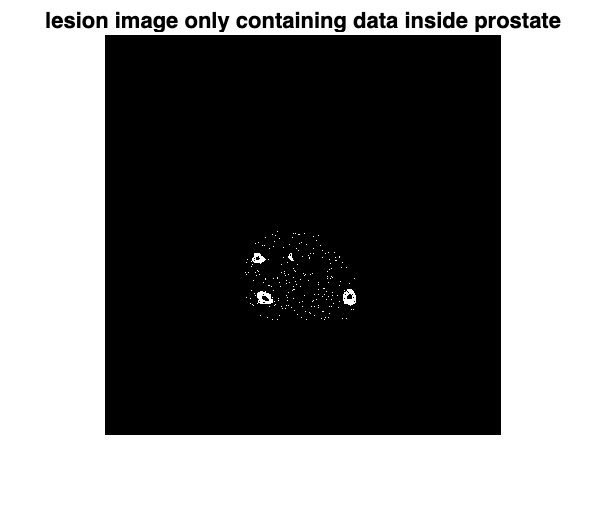

lesion_p = lesion_noise .* prostate;
figure
imshow(lesion_p)
title("lesion image only containing data inside prostate")

The lesions that we wanted to isolate had holes in them, so we had to remove the holes before isolating. I used MATLAB's hole-filling operation imfill() with the parameter "holes" so it would only fill internal holes instead of any holes that happened to occur at the edge, as both lesions were near the center of the image. The result is below.

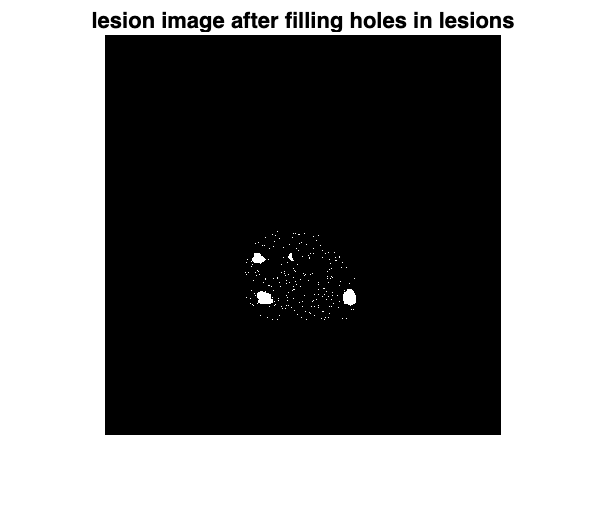

lesion_hole_fill = imfill(lesion_p, 'holes');
figure
imshow(lesion_hole_fill)
title("lesion image after filling holes in lesions")

After filling the holes, I used an opening operation. The structuring element was a disk with a size larger than the unwanted lesion/extra points in the image, but not larger than the relevant regions. After trial and error, I found that a disk of size 14 gave a result that was similar to the provided example. The result is shown below.

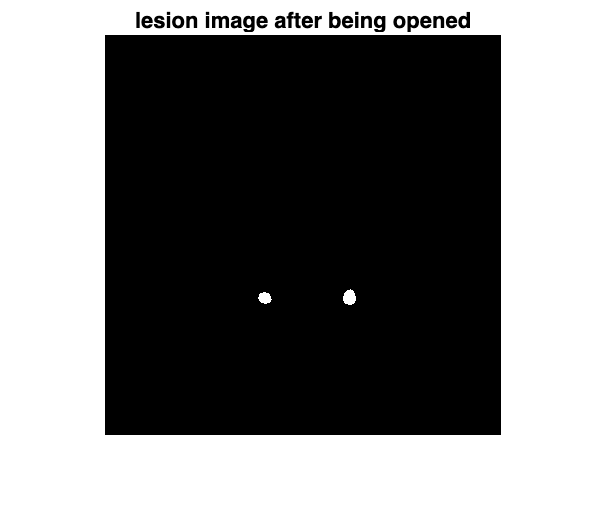

% creating structuring element
B = create_struct(14);

% applying opening operation
lesion_opened = imopen(lesion_hole_fill,B);

% display
figure
imshow(lesion_opened)
title("lesion image after being opened")

### Question 2

For this task, the area around the tumor needed to be isolated. The boundary extraction morphological operation only provides the boundary of the component itself; if that operation was used, it would highlight a section that was a part of the lesion, not around it. For this reason, I chose to modify the boundary extraction operation. Instead of eroding the image, I chose to dilate it, creating an artifically enlarged lesion. The result is shown below.

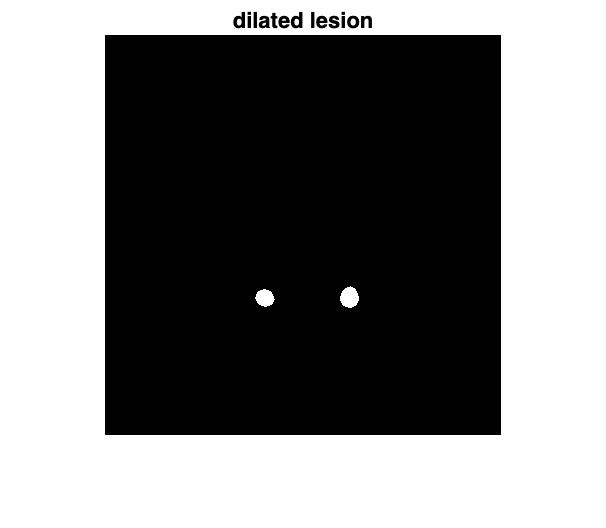

lesion_dilated = imdilate(lesion_opened, create_struct(10));
figure
imshow(lesion_dilated)
title("dilated lesion")

I then subtracted the original image from the dilated image so that there was an outline around the tumor rather than an outline inside it.

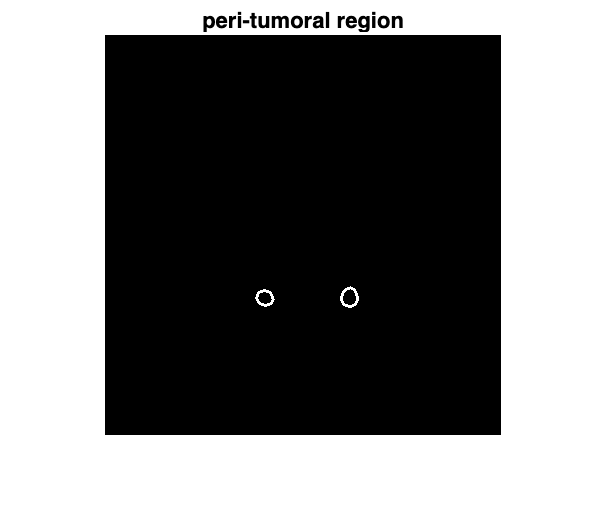

lesion_boundary = lesion_dilated - lesion_opened;
imshow(lesion_boundary)
title("peri-tumoral region")

Below, I have a display of the original lesion image with noise, the binary prostate image, the clinically relevant lesions, and the peri-tumoral regions.

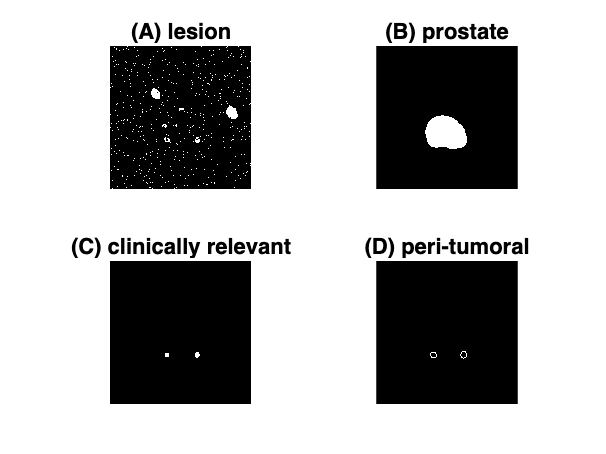

figure
subplot(2,2,1)
imshow(lesion_noise)
title("(A) lesion")
subplot(2,2,2)
imshow(prostate)
title("(B) prostate")
subplot(2,2,3)
imshow(lesion_opened)
title("(C) clinically relevant")
subplot(2,2,4)
imshow(lesion_boundary)
title("(D) peri-tumoral")

The next section contains a function I used to easily create disk-shaped structuring elements.

### Function - building a disk structuring element

function B = create_struct(size)

[cols, rows] = meshgrid(1:size,1:size);
center = size/2;
r = round(size/3);
B = double((rows - center).^2 + (cols - center).^2 <= r.^2);

end